cd(fileparts(matlab.desktop.editor.getActiveFilename))
close all; clearvars; clc

stroke_participant_list = ["P05", "P06", "P07", "P08", "P09"];
healthy_participant_list = ["P10", "P11"];
data_path = "D:\FRM\co-adaptive-learning";

participant_array = Participant.empty();
p_insertion_idx = 1;
dir_list = dir(data_path);

for i = 1:length(dir_list)
    dir_item = dir_list(i).name;
    if or(dir_item==".", dir_item=="..")
        continue
    end
    % Create participant object
    participant_id = regexprep(upper(dir_item), '-','')
    item_path = join([data_path, dir_item], "\");
    if ismember(participant_id, stroke_participant_list)
        p_handle = StrokeParticipant(item_path, participant_id);
    elseif ismember(participant_id, healthy_participant_list)
        p_handle = HealthyParticipant(item_path, participant_id);
    else
        error("Condition of participant %s is undefined", participant_id)
    end

    % Store participant object in particpant array
    participant_array(p_insertion_idx) = p_handle;
    p_insertion_idx = p_insertion_idx + 1;
end

participant_id = 'P05'

Loading Training File: D:\FRM\co-adaptive-learning\p-05\paretic\ml\TrainingData_20230308-190608_190709.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-05\paretic\hl\TaskData_20230308-192607.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-05\paretic\cl\TaskData_20230308-191220.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-05\nonparetic\ml\TrainingData_20230308-181939_182333.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P06'

Loading Training File: D:\FRM\co-adaptive-learning\p-06\paretic\ml\TrainingData_20230310-173032_173243.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-06\paretic\hl\TaskData_20230310-175819.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-06\paretic\cl\TaskData_20230310-173822.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-06\nonparetic\ml\TrainingData_20230310-164347_164805.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P07'

Loading Training File: D:\FRM\co-adaptive-learning\p-07\paretic\ml\TrainingData_20230313-125712_130002.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-07\paretic\hl\TaskData_20230313-132619.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-07\paretic\cl\TaskData_20230313-130615.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-07\nonparetic\ml\TrainingData_20230313-120910_121228.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P08'

Loading Training File: D:\FRM\co-adaptive-learning\p-08\paretic\ml\TrainingData_20230504-152730_153034.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-08\paretic\hl\TaskData_20230504-155210.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-08\paretic\cl\TaskData_20230504-153706.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-08\nonparetic\ml\TrainingData_20230504-141815_142323.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P09'

Loading Training File: D:\FRM\co-adaptive-learning\p-09\paretic\ml\TrainingData_20230517-140848_141004.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-09\paretic\hl\TaskData_20230517-143754.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-09\paretic\cl\TaskData_20230517-142321.kdf
Loading Training File: D:\FRM\co-adaptive-learning\p-09\nonparetic\ml\TrainingData_20230517-132109_132556.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Train

participant_id = 'P10'

Loading Training File: D:\FRM\co-adaptive-learning\p-10\healthy\ml\TrainingData_20231003-164321_164439.kdf
Training Kalman: 01 iteration(s)
Training Kalman: 02 iteration(s)
Training Kalman: 03 iteration(s)
Training Kalman: 04 iteration(s)
Training Kalman: 05 iteration(s)
Training Kalman: 06 iteration(s)
Training Kalman: 07 iteration(s)
Training Kalman: 08 iteration(s)
Training Kalman: 09 iteration(s)
Training Kalman: 10 iteration(s)
Loading Task File: D:\FRM\co-adaptive-learning\p-10\healthy\hl\TaskData_20231003-171017.kdf
Loading Task File: D:\FRM\co-adaptive-learning\p-10\healthy\cl\TaskData_20231003-165053.kdf


% Prune and label participant data
for i =1:numel(participant_array)
    p_handle = participant_array(i);
    disp(p_handle.participant_id);
    for j = 1:numEntries(p_handle.cond_dict)
        cond_keys = keys(p_handle.cond_dict);
        cond_vals = values(p_handle.cond_dict);
        cond  = cond_vals(j);
        for k=1:numEntries(cond.task_dict)
            task_keys = keys(cond.task_dict);
            task_vals = values(cond.task_dict);
            task = task_vals{k};
            task_type = task_keys(k);
            try
            pruned_ttbl = frm_deng_utils.prune_timetable(task.data_ttbl, task_type);
            catch
                disp([p_handle.participant_id, cond_keys(j), task_type])
            end
            if and(p_handle.participant_id == "P06", and(cond_keys(j) == "par", task_keys(k) == "hl"))
                task.events_tbl = task.events_tbl(3:end,:);
            end
            task.data_ttbl = frm_deng_utils.label_timetable(pruned_ttbl, task.events_tbl, task_type);
        end
    end
end

P05
P06
P07
P08
P09
P10


save("..\..\temp-data\participant_list", "participant_array")

P06 - paretic- human learning - remove first two events

p_handle = participant_array(6)

p_handle =   HealthyParticipant with properties:

    participant_id: 'P10'
         cond_dict: dictionary (string ⟼ Condition) with 1 entry


p_cond = "hlt";
p_task = "cl";
task_data = p_handle.cond_dict(p_cond).task_dict{p_task}.data_ttbl;
task_events = p_handle.cond_dict(p_cond).task_dict{p_task}.events_tbl;
if iscell(task_events{:,"TargOnTS"})
event_starts = ismember(task_data{:,"NIP Time"}, cell2mat(task_events{:,"TargOnTS"}));
else
    event_starts = ismember(task_data{:,"NIP Time"}, task_events{:,"TargOnTS"});
end 
event_stops = ismember(task_data{:,"NIP Time"}, task_events{:,"TrialTS"});

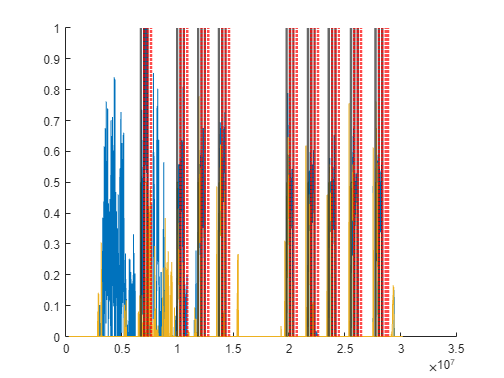

figure
hold on
plot(task_data.("NIP Time"), task_data.("Targets"))
plot(task_data.("NIP Time"), task_data.("Kalman"))
xline(task_data{event_starts, "NIP Time"}, 'LineWidth', 2)
xline(task_data{event_stops, "NIP Time"}, 'LineWidth', 2, 'Color','r', 'LineStyle',':')
hold off